%Skaitymas is windows forms programos sugeneruoto failo
msfile = fopen('received_dataNumzintas.txt','r');

formatSpec = ['%d'];

msdata = fscanf(msfile,formatSpec, [1 inf]);

plot(msdata)

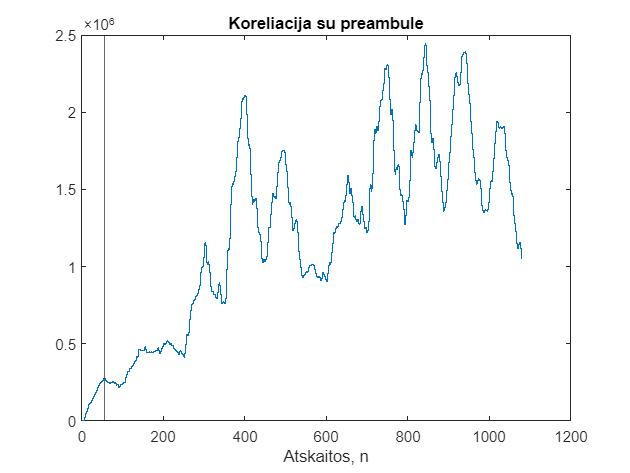

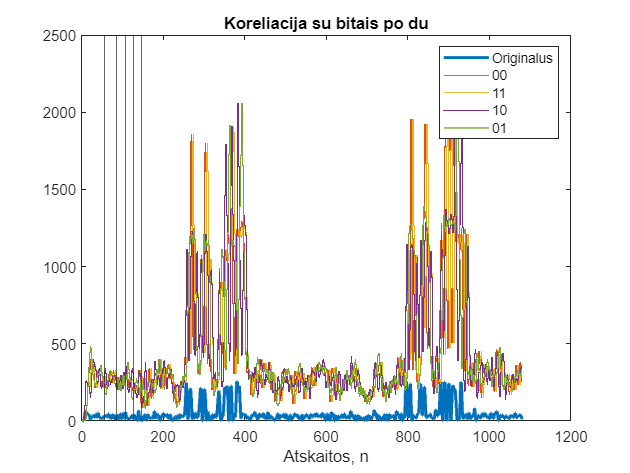

%Irasyti sugeneruota signala i txt faila generavimui
clear
[idealSignal1, noisySignal1, discretizedSignal1, ADCsignal1, ADCpreambule1] = GenerateSignal("101101", 1);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal("000010", 1);
signalaIrasyti = [ADCsignal1, ADCsignal2];
%signalaIrasyti = [idealSignal1(1:10:length(idealSignal1)), zeros(1, 100), idealSignal2(1:10:length(idealSignal2))];

[konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(signalaIrasyti, ADCpreambule1, 1);

length(signalaIrasyti)

ans = 1080

%Bandom csv
testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(signalaIrasyti)
    temp = dec2bin(signalaIrasyti(i), 10);
    fprintf(testVoltage,'%s\n',temp);
end
fclose(testVoltage);

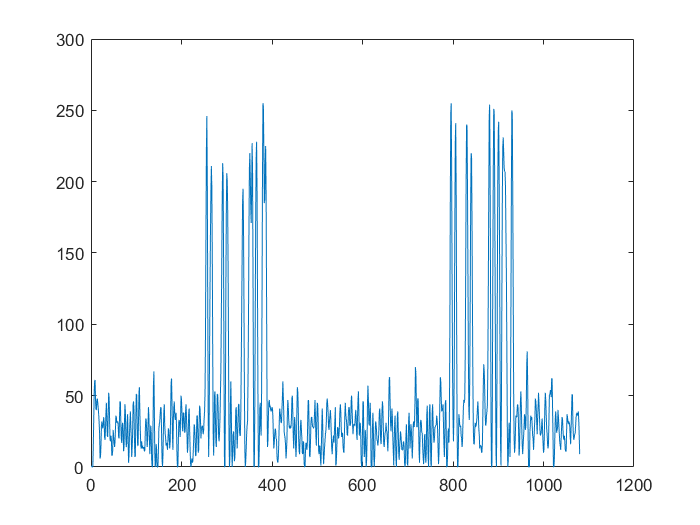

plot(signalaIrasyti)

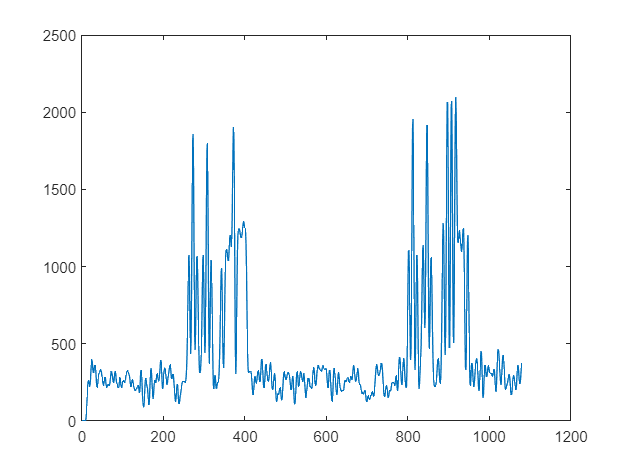

plot(konvSignalai(1, :))

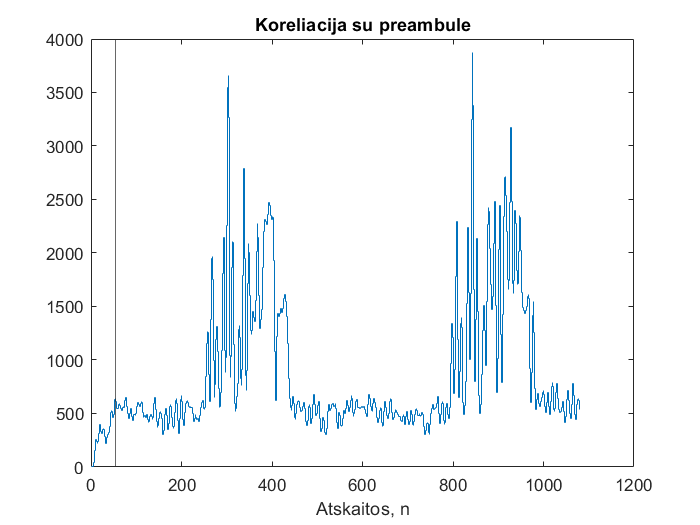

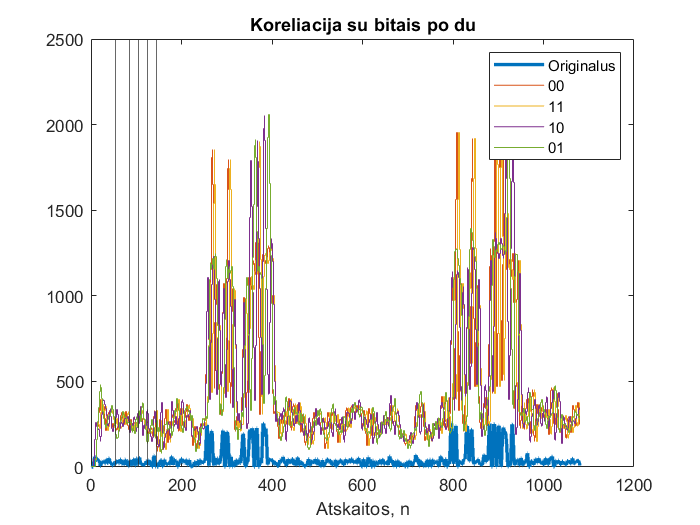

preambule = [ones(1, 5), zeros(1, 5), ones(1, 5), zeros(1, 20), ones(1, 5), zeros(1, 5), ones(1, 5)];
[konvSignalaii, konvPavadinimaii, konvLaikaii] = SignaluKonvoliucija(signalaIrasyti, preambule, 1);

%Duomenu emimas is modelsim
%IMIMAS IS MODELSIMO
%{
msfile = fopen('list.txt','r');
pliusas = char(43);
formatSpec = ['%d %d %d %d %d %d %d %d'];

msdata = fscanf(msfile,formatSpec, [8 inf]);

fclose(msfile);

% time +4 arrIndex  adcout 00 01 10 11

for i = 1:length(msdata(4, :))
    %msdata(4, i) = bin2dec(string(msdata(4, i)));
end

figure
stairs(msdata(5, :))
hold on
stairs(msdata(7, :))
hold off

stairs(konvoliucija5)
hold on
stairs(konvoliucija3)
hold off
figure
stairs(msdata(4, :)*10, 'LineWidth',2)
hold on
stairs(msdata(5, :))
stairs(msdata(6, :))
stairs(msdata(7, :))
stairs(msdata(8, :))
legend("OG", "00", "01", "10", "11")

figure

stairs(msdata(5, :))
hold on
legend( "FPGA 00", "Matlabo 00")
hold off
%}


%Irasyti MIF failus atminciai uzpildyti
%Irasyti failaa
%{
testVoltage = fopen('testVoltage.txt','w');
preambuleVoltage = fopen('idealPreambuleVoltage.txt','w');
idealOne = fopen('idealOneVoltage.txt','w');
idealZero = fopen('idealZeroVoltage.txt','w');
for i = 1:length(ADCsignal)
    temp = dec2bin(ADCsignal(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end
for i = 1:length(ADCpreambule)
    temp = dec2bin(ADCpreambule(i), 8);
    fprintf(preambuleVoltage,'%s\n',temp);
end
for i = 1:length(idealOne)
    temp = dec2bin(idealOne(i), 8);
    fprintf(idealOne,'%s\n',temp);
    temp = dec2bin(idealZero(i), 8);
    fprintf(idealZero,'%s\n',temp);
end
fclose(testVoltage);
fclose(preambuleVoltage);
fclose(idealOne);
fclose(idealZero);
%}


idealSignal2 = idealSignal.';
idealSignal22 = arrayfun(@num2str,idealSignal2,'un',0);

for i = 1:length(idealSignal22)
    temp = sprintf(",%1.4f", idealSignal2(i));
    temp = strrep(temp,'.',',');
    idealSignal22(i) = cellstr(temp);
end
%Irasyti csv
%arba writematrix(signalas, 'aaa.csv')
%writecell(idealSignal22,'IdealusSignalas.csv')

%bandom i rigolio txt
generatorVoltageText = fopen('generatorVoltageText.txt','w');
for i = 1:length(idealSignal)
    %fprintf(generatorVoltageText,'%d \n',idealSignal(i));
end

for i = 1:length(idealSignal22)

end

fclose(generatorVoltageText);

fdiskret = 10E6;
tdiskret = 1/fdiskret;
    
tprescaler = 10;
idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), 0*ones(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [0*ones(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];
idealOne = idealOne(1:10:length(idealOne));
idealZero = idealZero(1:10:length(idealZero));
[~, ~, ~, ~, ADCpreambule] = GenerateSignal("101101", 1);

ADCpreambule = ADCpreambule(1:10:length(ADCpreambule));
zeroone = [idealZero, idealOne, zeros(1, 12)];
oneone = [idealOne, idealOne, zeros(1, 12)];
onezero = [idealOne, idealZero, zeros(1, 12)];
zerozero = [idealZero, idealZero, zeros(1, 12)];

funkcijuFailas = fopen('Conv_func_data_wide.mif','w');
duomenisIrasyti = [ADCpreambule(1:16),ADCpreambule(17:25), zeros(1, 7), ADCpreambule(26:41), ADCpreambule(42:50), zeros(1, 7), zeroone, oneone, onezero, zerozero, zeros(1, 16*4)]; %Praembule, idealOne, idealZero

fprintf(funkcijuFailas, "WIDTH=128;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=BIN;\nCONTENT BEGIN \n", 16);

for i = 0:16:length(duomenisIrasyti)-16
    irasymoEilute = "";
    for y = 1:1:16
       irasymoEilute = append(irasymoEilute, reverse(dec2bin(duomenisIrasyti(i+y), 8)));
    end
    irasymoEilute = reverse(irasymoEilute);

    %temp = dec2bin(ADCpreambule(1), 8)
    %fprintf(funkcijuFailas,'%s\n',temp);
    fprintf(funkcijuFailas,'%i : %s;\n',round(i/16), irasymoEilute);
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);